# RoadRunner - Simulink cosimulation: 制御アルゴリズムの比較

## 変数、RoadRunnerをクリーンアップ

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;

## RoadRunnerをMATLABから起動する

rrApp = roadrunner();

% 必要なシナリオファイル, behaviorファイルをコピー
rrProjectPath = rrApp.status.Project.Filename;
copyfile("pathFollowingUtil/TrajectoryFollowBehavior14DoF.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscene", fullfile(rrProjectPath, "Scenes/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscenario", fullfile(rrProjectPath, "Scenarios/"));

behaviorName = "TrajectoryFollowBehavior14DoF.rrbehavior";
% シナリオを起動　シーンはシナリオと紐づいているため、自動でシーンも開く
rrApp.openScenario("slopeTest14DoF");
rrApp.setScenarioVariable("EgoVehicleBehavior", "<PROJECT>/Assets/Behaviors/" + behaviorName); %behaviorファイルを設定

rrSim = rrApp.createSimulation();

Connection status: 1
Connected to RoadRunner Scenario server on localhost:60906, with client id {1a244c13-3769-4eb0-b2f3-8c712dac39b5}


setRRSCameraMode(rrApp, "follow", actorID=1);
rrSim.set("PacerStatus", "Off");
rrSim.set("MaxSimulationTime", 14);
set(rrSim,"Logging","on");

% RoadRunnerの情報をSimulinkで取得するため、Busオブジェクトを定義
% To support Reader and Writer blocks, some bus objects must be loaded
load(fullfile(matlabroot,'toolbox','driving','drivingdata','rrScenarioSimTypes.mat'));

addpath("pathFollowingUtil");
helperSLTrajectoryFollowerWithRRScenarioSetup(); %車両ダイナミクスパラメータや制御パラメータを設定
% % Simulinkのモデルを開く
model_name = 'TrajectoryFollowVehicleWith14DoF.slx';
open_system(model_name);


% RoadRunnerとSimulinkの実行ステップサイズを揃える
timeStep = 0.01;
RRtimeStep = 0.1;
rrSim.set("StepSize", RRtimeStep);

## モデル予測制御で車両を制御

useDynamicsStanley = true; %シナリオの軌跡通りに動かすSimulinkモデル
vehicleVariant = "3DOF";

% RoadRunnerから車両初期値を取得し、車両モデルにセット
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName, ...
    controlMode="mpc_mod");

state_init = mpcstate(mpc_base);

   Assuming no disturbance added to measured output #2.
   Assuming no disturbance added to measured output #1.
   Assuming no disturbance added to measured output #3.


state_init.Plant = [egoInitialPoseCG.CurrVelocity 0,...
    0, 0,...
    deg2rad(egoInitialPoseCG.CurrYawRate) 0];%Vx, ax, Vy, Yaw(rad), YawRate(rad/s), Y
state_init.Covariance = eye(6, 6) * 0.01;

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

error("stop");

stop


% logを取得
rrLog = get(rrSim,"SimulationLog");

% 車両の速度を取得
velocityAgent3 = get(rrLog,'Velocity','ActorID',1); % Actor1の速度取得
time3 = [velocityAgent3.Time];% Actor1の時刻取得

% 車両の動きを取得
poseActor3 = rrLog.get('Pose','ActorID',1);
positionActor3_x = arrayfun(@(x) x.Pose(1,4),poseActor3);
positionActor3_y = arrayfun(@(x) x.Pose(2,4),poseActor3);

## 比較プロット

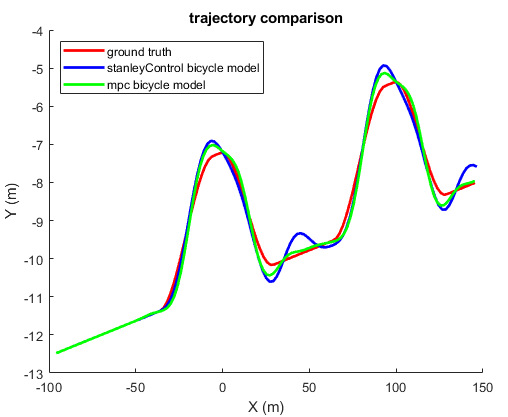

figure;
helperPlotVelocity(time1, velocityAgent1, time2, velocityAgent2, time3, velocityAgent3);
title("EgoSpeed: groundTruth");

helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor2_x, positionActor2_y, positionActor3_x, positionActor3_y);

## モデル

元々のモデル

A　システム状態量：9つ,  

B　状態量への入力：2つ

C　状態量からの出力：３つ

D　出力への入力：３つ

状態量： 縦速度$V_x$、縦加速度$\dot{V_x}$, 横速度$V_y$, ヨー角速度$r$, 状態量2つ追加(space control), lag dynamics 3つ(速度, lateral deviation, relative yaw angle),  

入力: 縦加速度$\dot{V_x}$, ステアリング角度$\delta$+curvature disturbance

出力：縦速度$V_x$, 横速度$V_y$, ヨー角速度$r$

useDynamicsStanley = true; %シナリオの軌跡通りに動かすSimulinkモデル
vehicleVariant = "3DOF";

controlMode = 'mpc_mod';%制御モデルを切り替え
% RoadRunnerから車両初期値を取得し、車両モデルにセット
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName, ...
    controlMode=controlMode);
numReferencePose = 1;

state_init = mpcstate(mpc_base);
% state_init.Plant = [egoInitialPoseCG.CurrVelocity 0,...
%     0, deg2rad(egoInitialPoseCG.CurrPose(3)),...
%     deg2rad(egoInitialPoseCG.CurrYawRate) egoInitialPoseCG.CurrPose(2)];%Vx, ax, Vy, Yaw(rad), YawRate(rad/s), Y
state_init.Plant = [egoInitialPoseCG.CurrVelocity 0,...
    0, 0,...
    deg2rad(egoInitialPoseCG.CurrYawRate) 0];%Vx, ax, Vy, Yaw(rad), YawRate(rad/s), Y
state_init.Covariance = eye(6, 6) * 0.001;

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

The model States, Inputs, and Outputs variables are defined as follows:

- State variables: Lateral velocity $V_y$, yaw angle $\psi$, yaw angle rate $r$, global $Y$ position

- Input variable: Front steering angle $\delta$

- Output variable: Global $Y$ position and yaw angle $\psi$

$\[
  A =
  \left[ {\begin{array}{cc}
-\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0& 1 & 0 \\
     -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     1 & Vx & 0 & 0 \\
  \end{array} } \right]
\]$,    $\[
B = 
\left[ {\begin{array}{cc}
\frac{2C_f}{m} \\ 0 \\ \frac{2C_fl_f}{I_z} \\ 0
\end{array} } \right]
\]
$,    $\[
C = 
\left[ {\begin{array}{cc}
0 & 0 & 0 & 1 \\
0 & 1 & 0 & 0
\end{array} } \right]
\]
$,    $D = 0$

- State variables: Longitudinal velocity $V_x$, Longitudinal accelration$\dot{V_x}$, Lateral velocity $V_y$, yaw angle $\psi$, yaw angle rate $r$, global $Y$ position

- Input variable: Front steering angle $\delta$

- Output variable: Global $Y$ position and yaw angle $\psi$

$\[
  A' =
  \left[ {\begin{array}{cc}
     0 & 1 & 0 & 0 & 0 & 0\\
      0 & \frac{-1}{\tau} & 0 & 0 & 0 & 0\\ 
     0 & 0 & -\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0 & 0 & 0& 1 & 0 \\
     0 & 0 & -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     0 & 0 & 1 & Vx & 0 & 0 \\
  \end{array} } \right]
\]$,    $\[
B = 
\left[ {\begin{array}{cc}
 0 & 0 \\
 \frac{1}{\tau} & 0 \\
 0 & \frac{2C_f}{m}\\
 0 & 0 \\
 0 & \frac{2C_fl_f}{I_z}\\
 0 & 0
\end{array} } \right]
\]
$,    $\[
C = 
\left[ {\begin{array}{cc}
1 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 1 \\
0 & 0 & 0 & 1 & 0 & 0
\end{array} } \right]
\]
$,    $D = 0$

$\[
 \frac{d}{dt}
\left[  {\begin{array}{cc}
V_x \\
\dot V_x \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} } \right]  =
  \left[ {\begin{array}{cc}
     0 & 1 & \dot \psi & 0 & 0 & 0\\
      0 & \frac{-1}{\tau} & 0 & 0 & 0 & 0\\ 
     0 & 0 & -\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0 & 0 & 0& 1 & 0 \\
     0 & 0 & -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     0 & 0 & 1 & Vx & 0 & 0 \\
  \end{array} } \right]
\left[  \begin{array}{cc}
V_x \\
\dot V_x \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} \right]
\]$,    $\[
+\  
\left[ {\begin{array}{cc}
 0 & 0 \\
 \frac{1}{\tau} & 0 \\
 0 & \frac{2C_f}{m}\\
 0 & 0 \\
 0 & \frac{2C_fl_f}{I_z}\\
 0 & 0
\end{array} } \right]
\left[ {\begin{array}{cc}
a \\
\delta
\end{array} } \right]
\]
$,    $\[
C = 
\left[ {\begin{array}{cc}
1 & 0 & 0 & 0 & 0 & 0 \\
0 & 0 & 0 & 0 & 0 & 1 \\
0 & 0 & 0 & 1 & 0 & 0
\end{array} } \right]
\]
$,    $D = 0$


$$\[
 \frac{d}{dt}
\left[  {\begin{array}{cc}
V_x \\
\dot V_x \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} } \right]  =
  \left[ {\begin{array}{cc}
     0 & 1 & 0 & 0 & 0 & 0\\
      0 & \frac{-1}{\tau} & 0 & 0 & 0 & 0\\ 
     0 & 0 & -\frac{(2C_f+2C_r)}{mV_x} & 0 & -V_x-\frac{(2C_fl_f-2C_rl_r)}{mV_x} &0 \\
     0 & 0 & 0 & 0& 1 & 0 \\
     0 & 0 & -\frac{(2C_fl_f-2C_rl_r)}{I_zV_x} & 0 &-\frac{(2C_fl_f^2+2C_rl_r^2)}{I_zV_x} & 0 \\
     0 & 0 & 1 & 0 & 0 & 0 \\
  \end{array} } \right]
\left[  \begin{array}{cc}
V_x \\
\dot V_x \\
V_y \\
\psi \\
\dot \psi \\
Y
\end{array} \right]

+\  
\left[ {\begin{array}{cc}
 0 & 0 \\
 \frac{1}{\tau} & 0 \\
 0 & \frac{2C_f}{m}\\
 0 & 0 \\
 0 & \frac{2C_fl_f}{I_z}\\
 0 & 0
\end{array} } \right]
\left[ {\begin{array}{cc}
a \\
\delta
\end{array} } \right]
+
\left[ {\begin{array}{cc}
0 \\ 0 \\ 0 \\ 0 \\ -V_x \\ 0
\end{array} } \right]
\rho
\]
$$


$\dot Y = V_x\sin\psi + V_y \cos \psi
$となるため、非線形　$e = Y - Y_{ref}
$で表現が必要


$$\dot Y \simeq V_x \psi + V_y
$$



$$\dot e = \dot Y - \dot Y_{ref} = V_y - \dot Y_{ref} =  V_y - \int{a_{yref}} dt
$$


Vx = 20;
A = [0 1 0 0 0 0;
     0 -1/tau 0 0 0 0;
     0 0 -(2*Cf+2*Cr)/(m*Vx) 0 -Vx-(2*Cf*lf - 2*Cr*lr)/(m*Vx) 0;
     0 0 0 0 1 0;
     0 0 -(2*Cf*lf-2*Cr*lr)/(Iz*Vx) 0 -(2*Cf*lf^2+2*Cr*lr^2)/(Iz*Vx) 0;
     0 0 1 0 0 0];
B = [0 0; 1/tau 0; 0 2*Cf/m; 0 0; 0 2*Cf*lf/Iz; 0 0];
C = [1 0 0 0 0 0; 0 0 0 0 0 1; 0 0 0 1 0 0];
D = 0;
vehicle = ss(A,B,C,D);

nx = size(Ac,1);
nu = size(Bc,2);
M = expm([[Ac Bc]*Ts; zeros(nu,nx+nu)]);
A = M(1:nx,1:nx);
B = M(1:nx,nx+1:nx+nu);
C = Cc;
D = Dc;

% Nominal conditions for discrete-time plant
X = x;
U = u;
Y = C*x + D*u;
DX = A*x+B*u-x;

## 車両ダイナミクスとしてフルビークルモデル(14DoF)、制御をStanleyControlで実施

useDynamicsStanley = true; %シナリオの軌跡通りに動かすSimulinkモデル
vehicleVariant = "14DOF";

% controlMode = 'mpc';%制御モデルを切り替え
% numReferencePose = PredictionHorizon; %prediction horizonと同数のreference poseを出力
% RoadRunnerから車両初期値を取得し、車両モデルにセット
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName, ...
    controlMode="mpc");

% 事前に作成した地形マップをロード
load("gridMap_groundHeight_RT.mat");% RoadRunnerシーンをstlやfbxなどのメッシュファイルで出力し、２次元高さマップに変換して取得
hegihtMap = "2DMap"; %事前に用意した地形マップを使用するモード
debug_engine3D = false;%trueにするとUnreal Engineによる追加表示あり

% Unreal EngineシーンをEmptyに設定
load_system("sim3d_visualization");
Sim3DConfigPath = "sim3d_visualization/Simulation3DTerrain";
set_param(Sim3DConfigPath, "SourceFile", "");

% Simulationを開始する
set(rrSim,"SimulationCommand","Start");
% RoadRunner ScenarioのSimulation実行が終了するまで待機
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end
% logを取得
rrLog = get(rrSim,"SimulationLog");

% 車両の速度を取得
velocityAgent3 = get(rrLog,'Velocity','ActorID',1); % Actor1の速度取得
time3 = [velocityAgent3.Time];% Actor1の時刻取得

% 車両の動きを取得
poseActor3 = rrLog.get('Pose','ActorID',1);
positionActor3_x = arrayfun(@(x) x.Pose(1,4),poseActor3);
positionActor3_y = arrayfun(@(x) x.Pose(2,4),poseActor3);

rotationActor3_eulZYX = cell2mat(arrayfun(@(x) tform2eul(x.Pose, "ZYX")', poseActor3, 'UniformOutput', false))';
rotationActor3_pitch = rad2deg(rotationActor3_eulZYX(:, 3));

function helperPlotVelocity(time1, velocityAgent1, time2, velocityAgent2, time3, velocityAgent3)
    velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
    velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);
    velMagAgent3 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent3);


    % Plot the agent velocities with respect to simulation time using the plot function. Label the graph and the x and y axes.
    hold on
    plot(time1,velMagAgent1,"r")
    plot(time2,velMagAgent2,"b")
    plot(time3,velMagAgent3,"g")
    grid on
    title("Agent Velocities from RoadRunner Scenario")
    ylabel("Velocity (m/sec)")
    xlabel("Time (sec)")
    legend(["ground truth","stanleyControl bicyclemodel", "mpc bicyclemodel"], 'Location','southwest');
end
function helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor2_x, positionActor2_y, positionActor3_x, positionActor3_y)
    % hdMap = getMap(rrSim);
    % lanes = hdMap.map.lanes;
    % Loop through each of the lane specifications using a for loop and plot the lane coordinates.
    
    figure
    hold on
    % for i = 1:numel(lanes)
    %     control_points = lanes(i).geometry.values;
    %     x_coordinates = arrayfun(@(cp) cp.x,control_points);
    %     y_coordinates = arrayfun(@(cp) cp.y,control_points);
    %     plot(x_coordinates, y_coordinates, 'black');
    % end
    plot(positionActor1_x,positionActor1_y,"r","LineWidth",2);
    hold on;
    plot(positionActor2_x,positionActor2_y,"b","LineWidth",2);
    plot(positionActor3_x,positionActor3_y,"g","LineWidth",2);
    legend(["ground truth","stanleyControl bicycle model", "mpc bicycle model"], 'Location','northwest');
    title("trajectory comparison");
    ylabel("Y (m)");
    xlabel("X (m)");
end